# Time/frequency dependent fitness functions

This file gives the computations used in the paper "Social Learning and the Exploration-Exploitation Tradeoff" which uses adaptive dynamics and the replicator mutator equation to determine the evolution of exploration rate, seeing how nature would solve the exploration/exploitation issue. 

First, it clears the workspace, then loads the necessary functions definiting mutation kernels and fitness functions. The following cells perform some computations in this framework. 

To explore more functions, one can edit some of these blocks, for example seeing what happens in different games, like public goods games, or different time-varying fitness functions, like ones where the optimal trait jumps stochastically. 

## Initialize

clear; clc; % clear stored variables
close all % closes open figures

## Local Mutation Kernel

Here we define the local mutation kernel, which govens how offspring mutate for a given mutation rate $u$. 

This also defines $Q(u)$, given by how mutation beyond the boundaries is handled. The code for this is given in functions defined at the end of the file (as Matlab requires for local functions). 

To better visualize this, some rows of $Q(u)$ are plotted. 

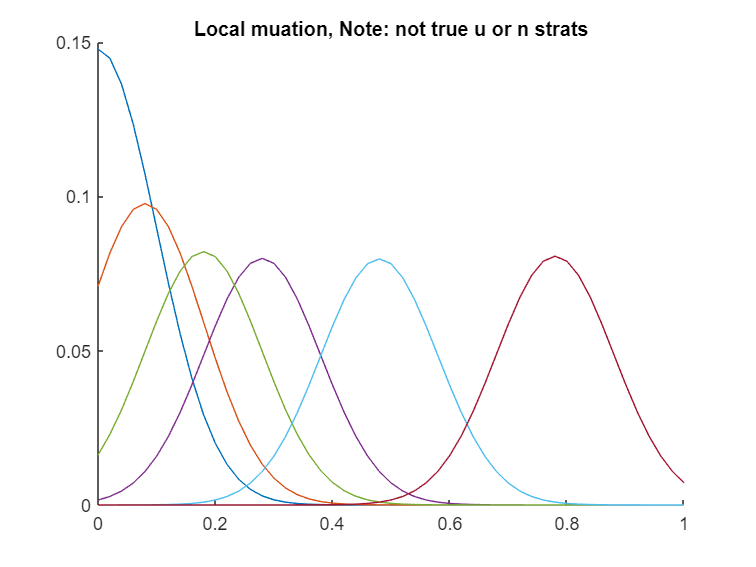

normal = @(xs, strat, u) normpdf(xs,strat,u); %exp(((xs-mean)/sigma).^2/2)/(sigma*sqrt(2*pi));
peak   = @(xs, strat, u) interp1([-10, strat-u/2, strat, strat+u/2, 10], [0, 0, 1, 0, 0], xs);
flat   = @(xs, strat, u) double(abs(xs-strat) < u/2);

spread_funct = normal;
spread_matrix_funct = @(u,n_strats) trunc_spread_matrix(u, spread_funct, n_strats);
% options: trunc_spread_matrix, accum_spread_matrix, circ_spread_matrix,
% integ_trunc_spread_matrix, integ_accum_spread_matrix, unif_spread_matrix

test_n = 51;
test_spread = spread_matrix_funct(0.1,test_n);
figure
hold on
to_show = [1, 5, 10, 15, floor(0.2*test_n), floor(0.5*test_n), floor(0.8*test_n)];
for i=1:length(to_show)
    plot(linspace(0,1,test_n), test_spread(:, to_show(i)))
end
title("Local muation, Note: not true u or n strats")
hold off % note some are higher / lower because of normalization

## Fitness

Here we define the fitness we want to investigate. 

To help visualize this, a plot is given. 

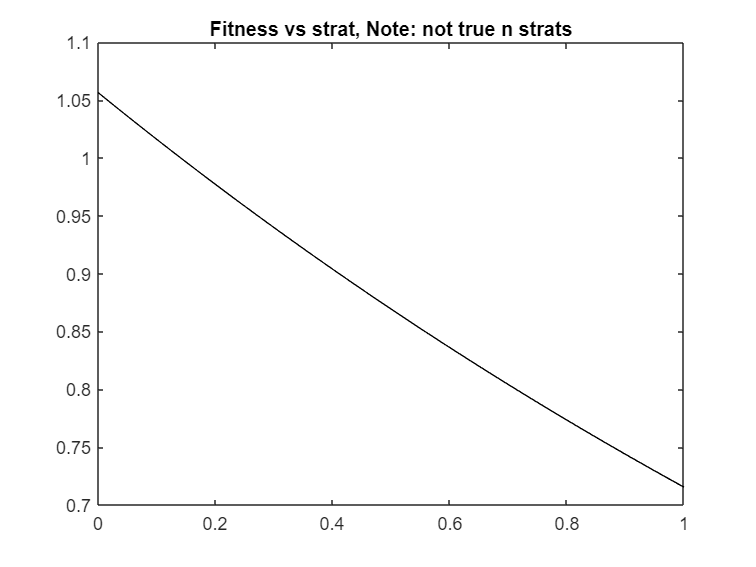

indic = @(x,a,b) x>a && x<b;

min_fit = @(strats) 1+min(strats, 1-strats);

% not functions, so they don't change each time fitness is called
rand_fit_1 = @(strats) 1+interp1(linspace(0,1,10),rand(1,10), strats); 
rand_fit_2 = @(strats) 1+interp1([0, sort(rand(1,10-2)), 1], rand(1,10), strats); 

HD = @(val) [[val-1, 2*val]; [0, val]];
T = 4; R = 3; P = 2; S = 1; % need T>R>P>S for PD
PD = [[R, S]; [T, P]];
coordination = eye(2);
assurance = [[2, 0]; [0, 1]]; % ~ SH
AC = [[0, 1]; [1, 0]]; % anti-coordination
SH = [[4, 1]; [3, 2]]; % stag hunt


payoff_to = @(game, y,x) exp(game(1,1)*x*y + game(1,2)*(1-x)*y+game(2,1)*x*(1-y) + game(2,2)*(1-x)*(1-y));
game_fit = @(game) @(t, dist,strats) arrayfun(@(x) payoff_to(game, x,strats*dist), strats);

%game = SH;
%a = game(1,1); b = game(1,2); c = game(2,1); d = game(2,2);
%payoff_to = @(y,x) exp(a*x*y + b*(1-x)*y+c*x*(1-y) + d*(1-x)*(1-y));
%game_fit = @(t, dist,strats) arrayfun(@(x) payoff_to(x,strats*dist), strats);



fitness = game_fit(HD(0.5));

test_n = 101;
figure
dist = zeros(test_n,1);
dist(90) = 1;
plot(linspace(0,1,test_n), fitness(0,dist,linspace(0,1,test_n)), 'k')
title("Fitness vs strat, Note: not true n strats")

## PD

Here we see what happens when fitness comes from the Prisoner's Dilemma game. 

Elapsed time is 10.448232 seconds.
Elapsed time is 11.300912 seconds.
Elapsed time is 9.796970 seconds.
Elapsed time is 12.066531 seconds.
Elapsed time is 11.166692 seconds.


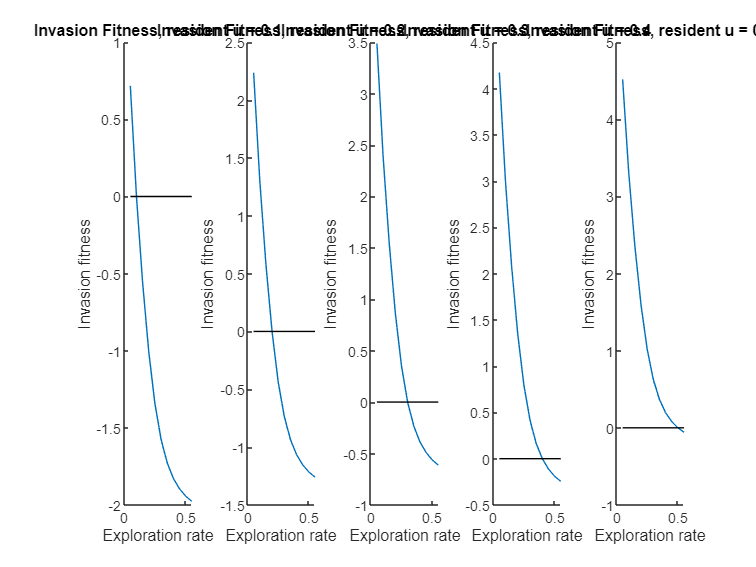

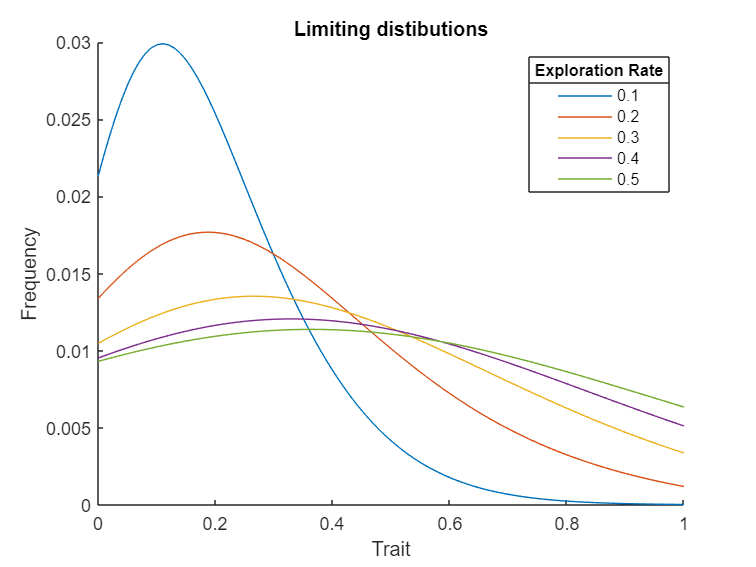

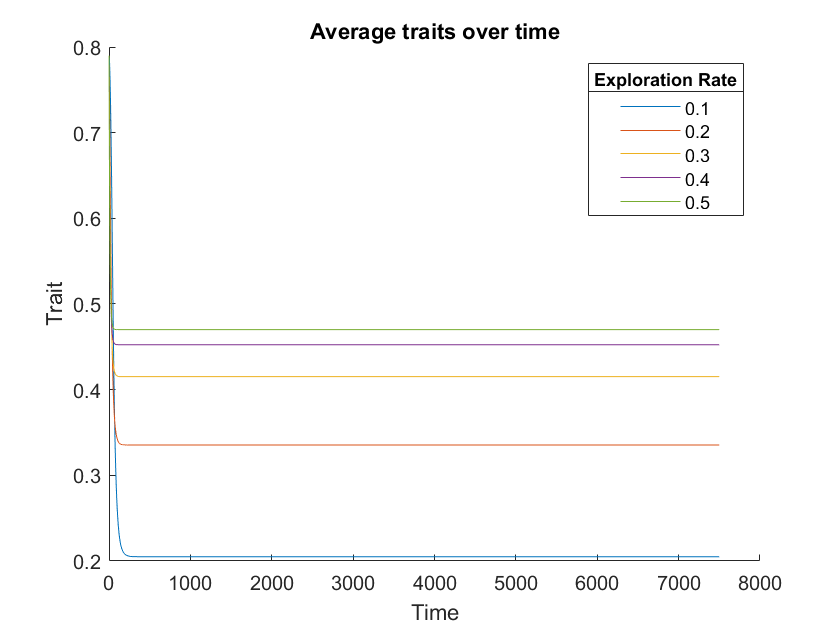

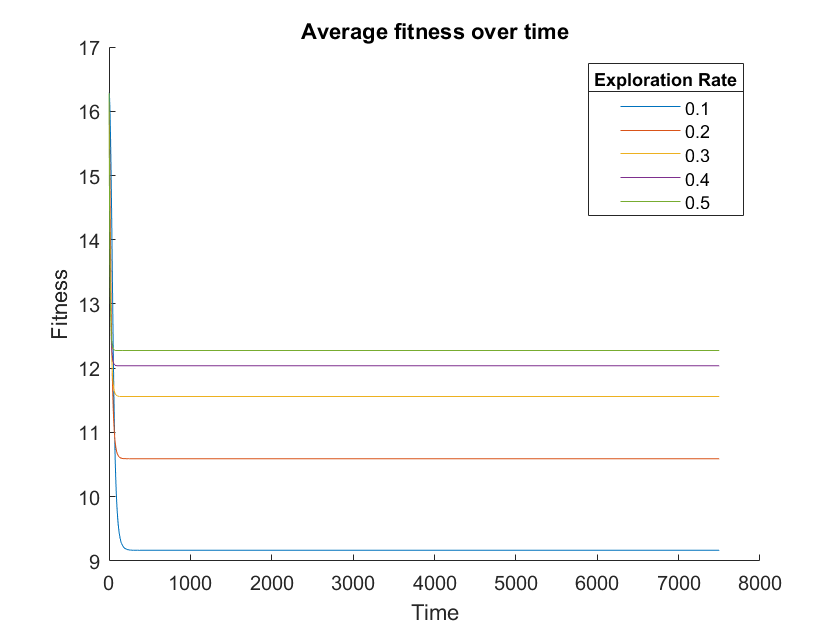

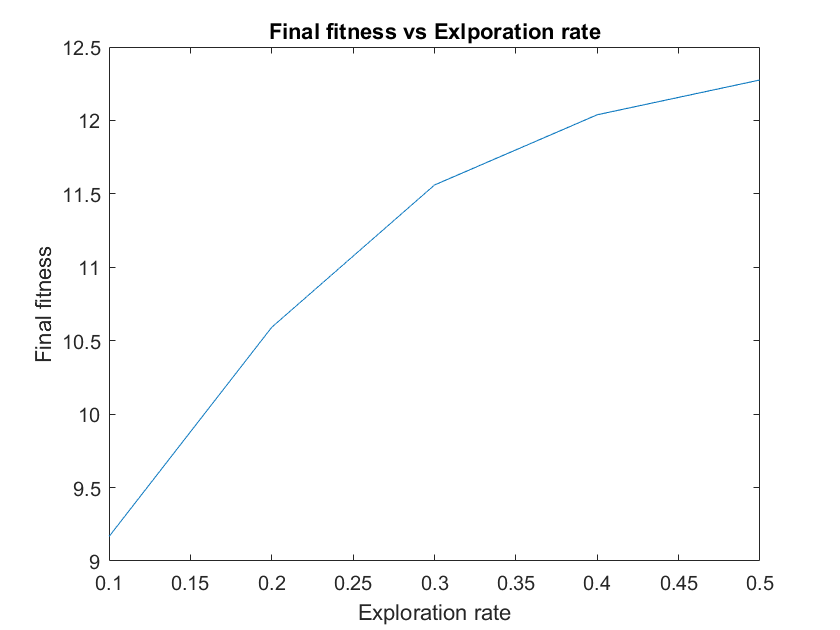

fitness = game_fit(PD);
spread_matrix_funct = @(u,n_strats) trunc_spread_matrix(u, spread_funct, n_strats);
%spread_matrix_funct = @(u,n_strats) accum_spread_matrix(u, spread_funct, n_strats);

us = [0.1, 0.2, 0.3, 0.4, 0.5]; % mutation rates to run. 
query_us   = 0.05*(1:11); % should span a bit more than the us. 

n_strats  = 101;  % fineness of strategy space discretization
delta_t   = 0.01; % time step for solving the Replicator-Mutator Equation
n_steps   = 7500;
init_dist = zeros(n_strats,1);
init_dist(80) = 1;
init_dist = init_dist / sum(init_dist);

[avg_strats_record, avg_fit_record, dist_record] = all_the_plots(fitness, spread_matrix_funct, us, ...
    query_us, n_strats, delta_t, n_steps, init_dist); % could make separate functions for each plotting. 

## For HD, c = 0.5

Then the hawk-dove game, with the cost of competetion equal to 0.5. The following cells investigate what happens with higher or lower costs. 

Elapsed time is 12.752991 seconds.
Elapsed time is 9.795052 seconds.
Elapsed time is 9.744762 seconds.
Elapsed time is 11.525115 seconds.
Elapsed time is 14.586315 seconds.


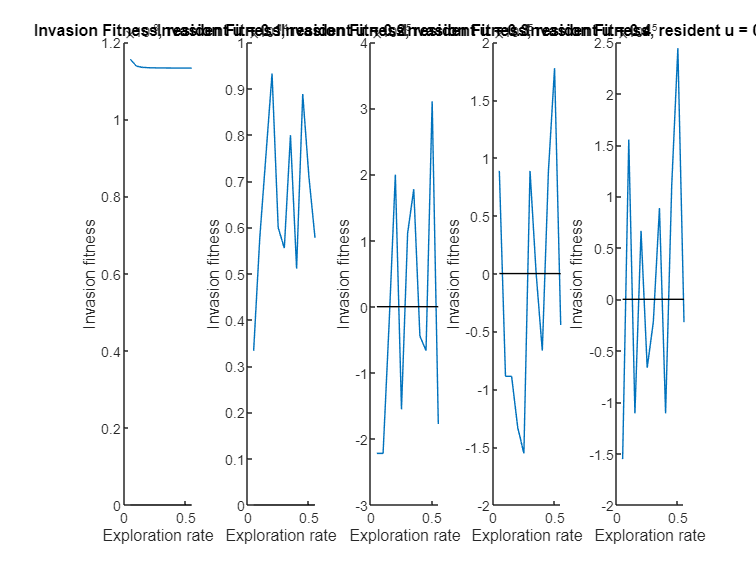

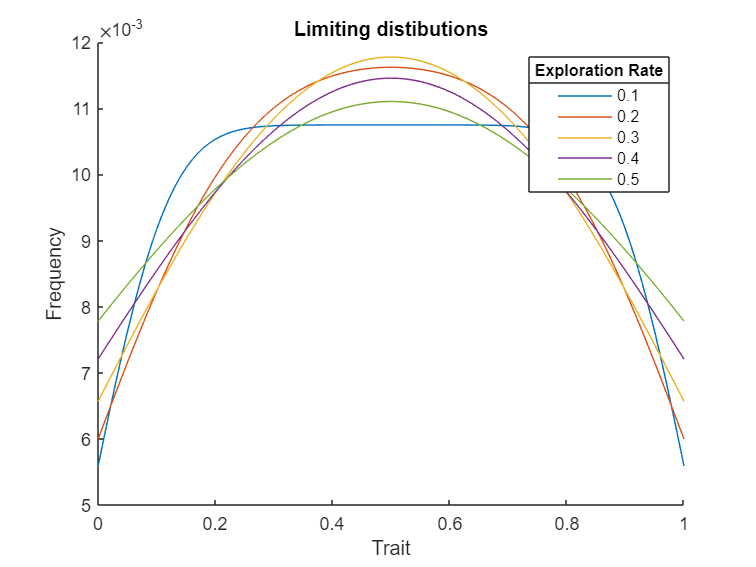

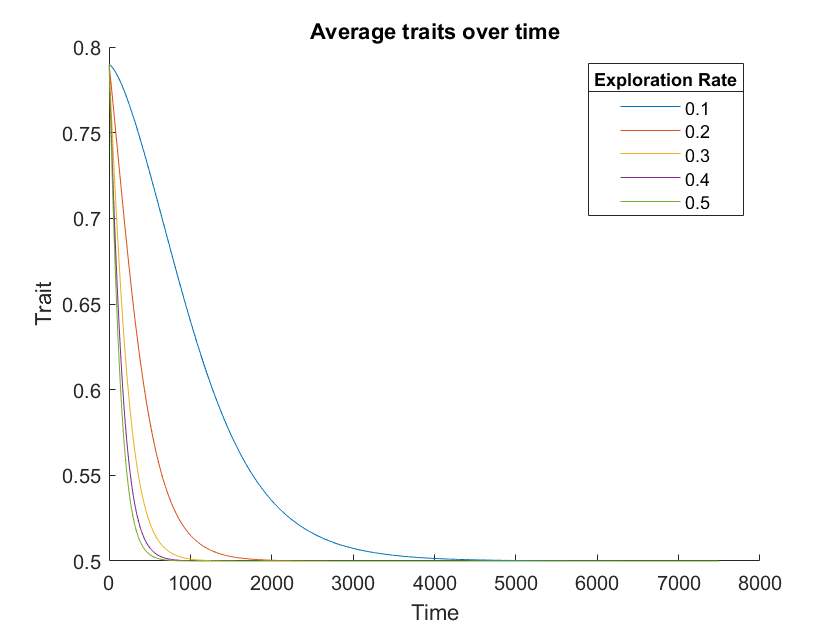

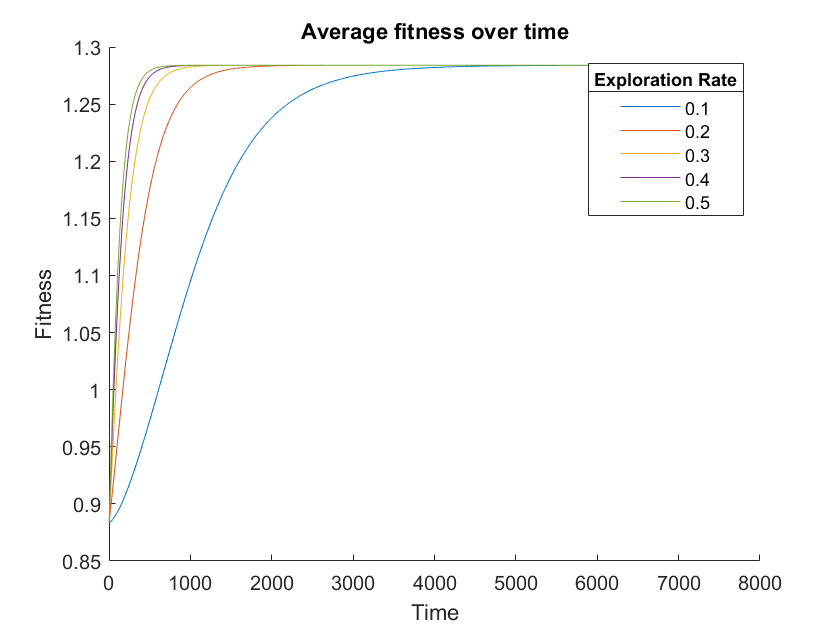

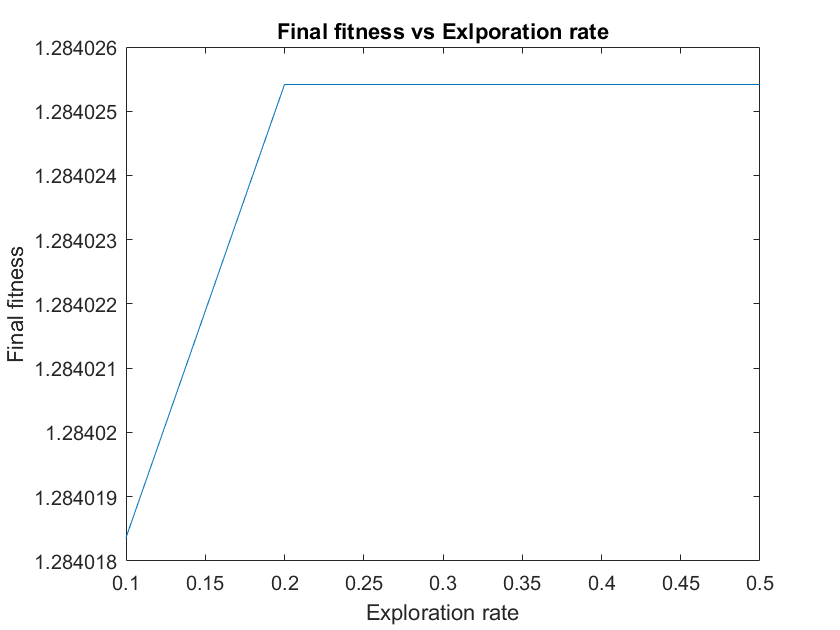

fitness = game_fit(HD(0.5));
spread_matrix_funct = @(u,n_strats) trunc_spread_matrix(u, spread_funct, n_strats);
%spread_matrix_funct = @(u,n_strats) accum_spread_matrix(u, spread_funct, n_strats);

us = [0.1, 0.2, 0.3, 0.4, 0.5]; % mutation rates to run. 
query_us   = 0.05*(1:11); % should span a bit more than the us. 

n_strats  = 101;  % fineness of strategy space discretization
delta_t   = 0.01; % time step for solving the Replicator-Mutator Equation
n_steps   = 7500;
init_dist = zeros(n_strats,1);
init_dist(80) = 1;
init_dist = init_dist / sum(init_dist);

[avg_strats_record, avg_fit_record, dist_record] = all_the_plots(fitness, spread_matrix_funct, us, ...
    query_us, n_strats, delta_t, n_steps, init_dist); % could make separate functions for each plotting. 


% bimodal for small MR if trunc_accum is used (plot without endpoints). 

## HD with c < 0.5

Elapsed time is 12.594842 seconds.
Elapsed time is 9.959967 seconds.
Elapsed time is 15.404369 seconds.
Elapsed time is 9.558124 seconds.
Elapsed time is 9.051998 seconds.


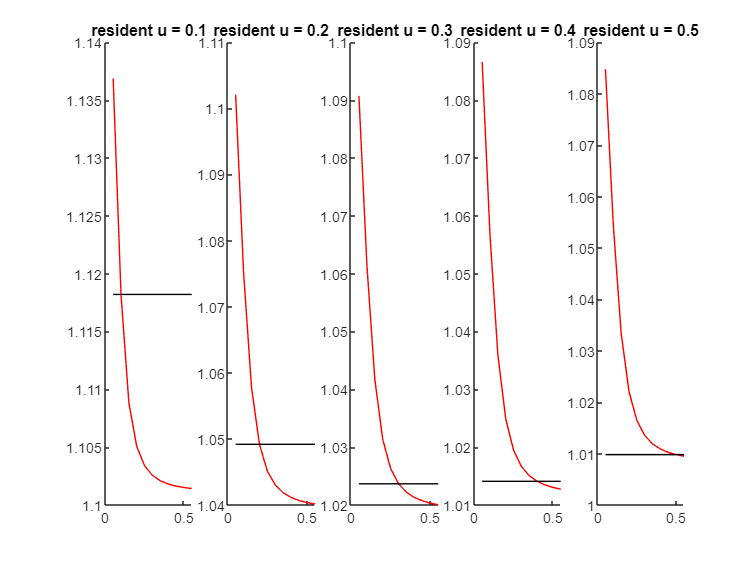

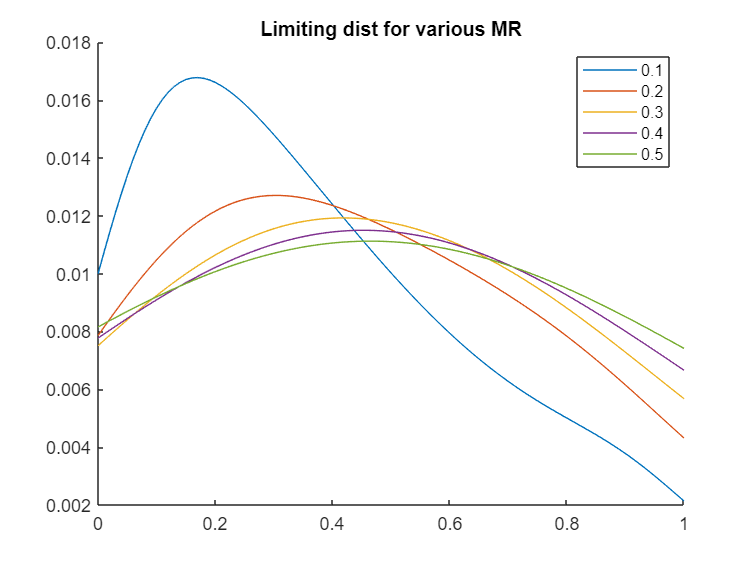

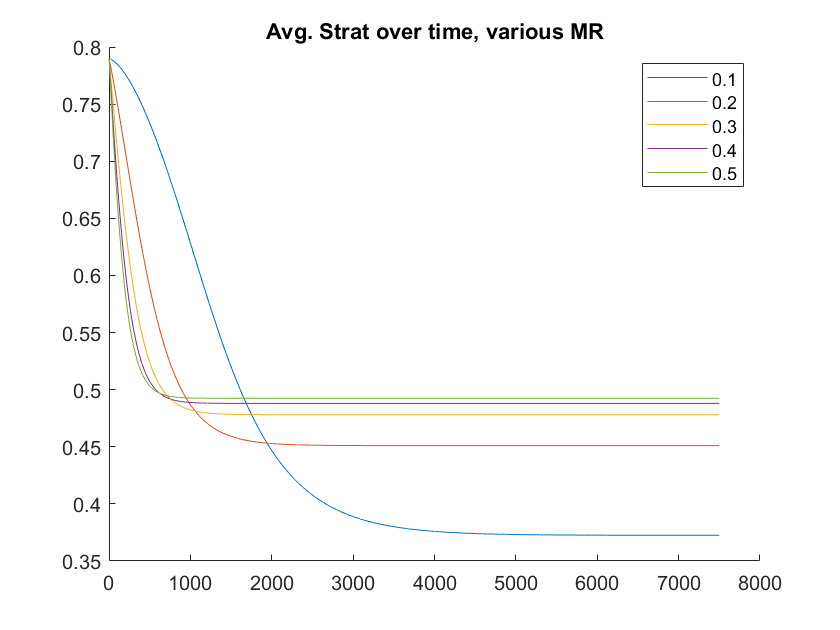

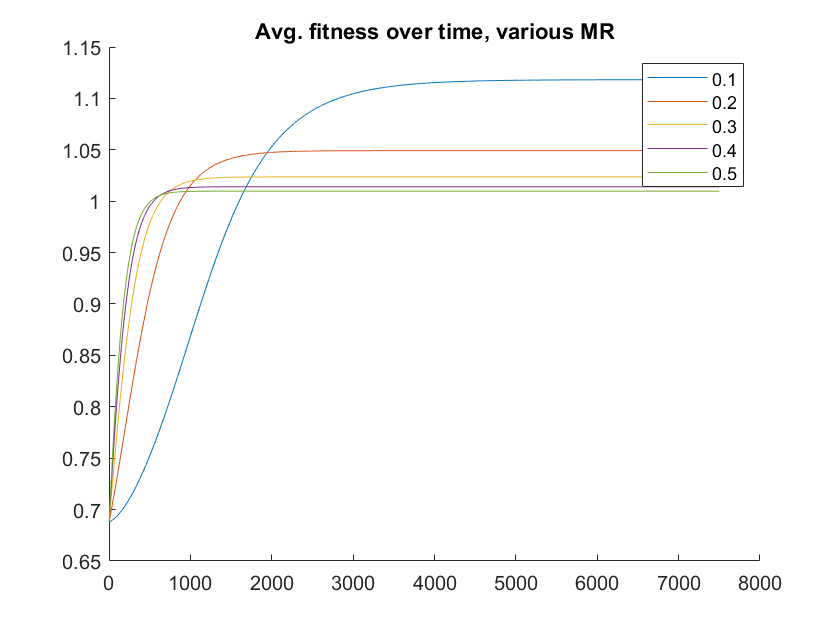

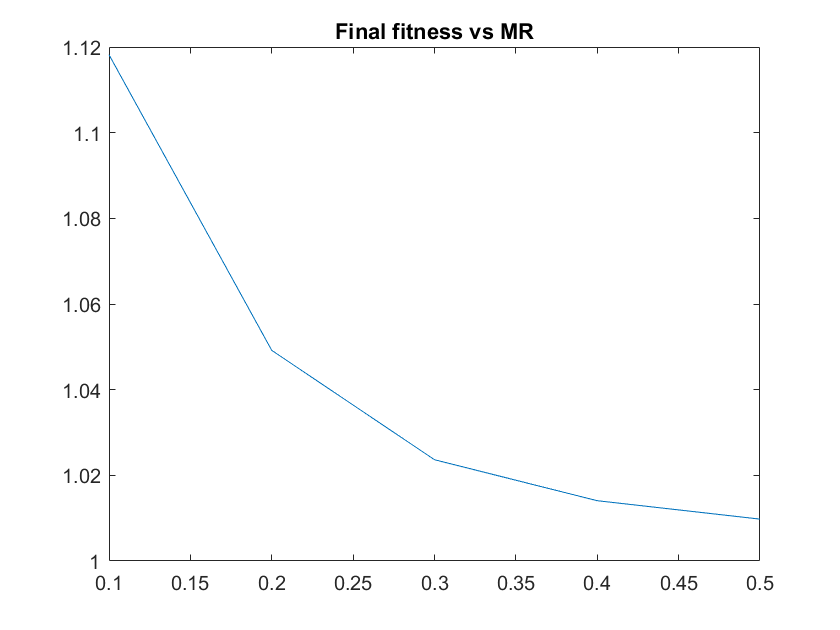

fitness = game_fit(HD(0.25));
spread_matrix_funct = @(u,n_strats) trunc_spread_matrix(u, spread_funct, n_strats);
%spread_matrix_funct = @(u,n_strats) accum_spread_matrix(u, spread_funct, n_strats);

us = [0.1, 0.2, 0.3, 0.4, 0.5]; % mutation rates to run. 
query_us   = 0.05*(1:11); % should span a bit more than the us. 

n_strats  = 101;  % fineness of strategy space discretization
delta_t   = 0.01; % time step for solving the Replicator-Mutator Equation
n_steps   = 7500;
init_dist = zeros(n_strats,1);
init_dist(80) = 1;
init_dist = init_dist / sum(init_dist);

[avg_strats_record, avg_fit_record, dist_record] = all_the_plots(fitness, spread_matrix_funct, us, ...
    query_us, n_strats, delta_t, n_steps, init_dist); % could make separate functions for each plotting. 

## HD with c > 0.5

Elapsed time is 10.642918 seconds.
Elapsed time is 10.902005 seconds.
Elapsed time is 9.417742 seconds.
Elapsed time is 9.417709 seconds.
Elapsed time is 11.380220 seconds.


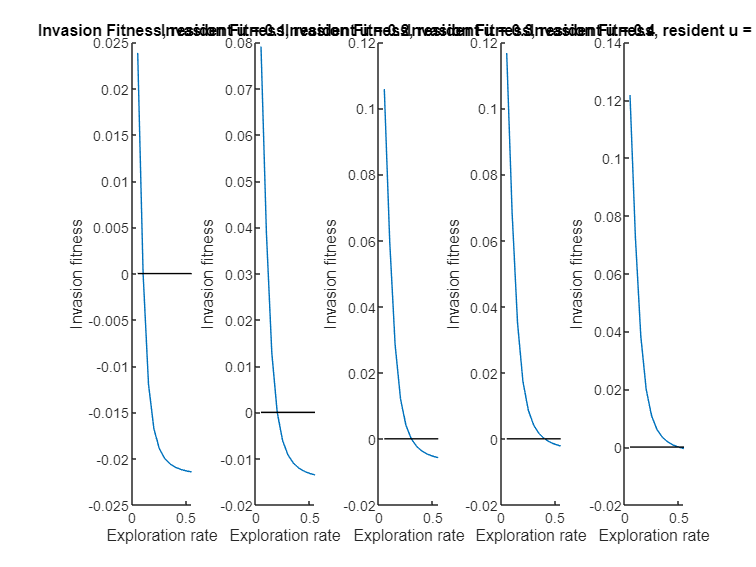

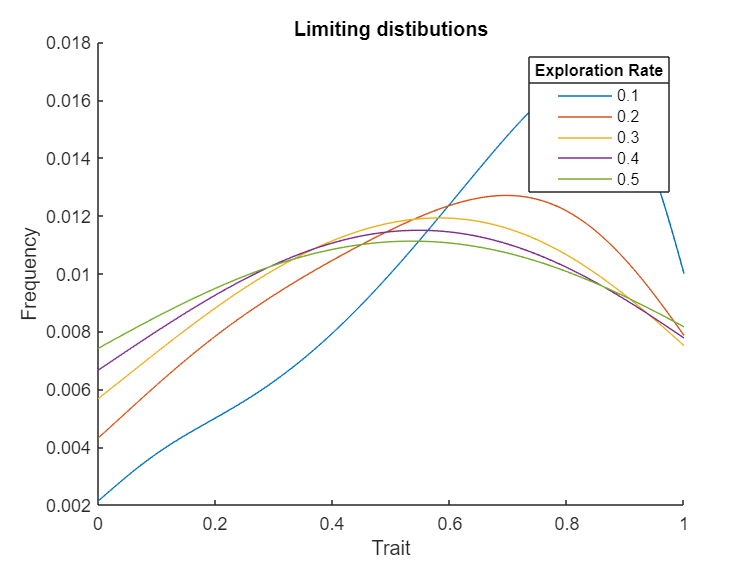

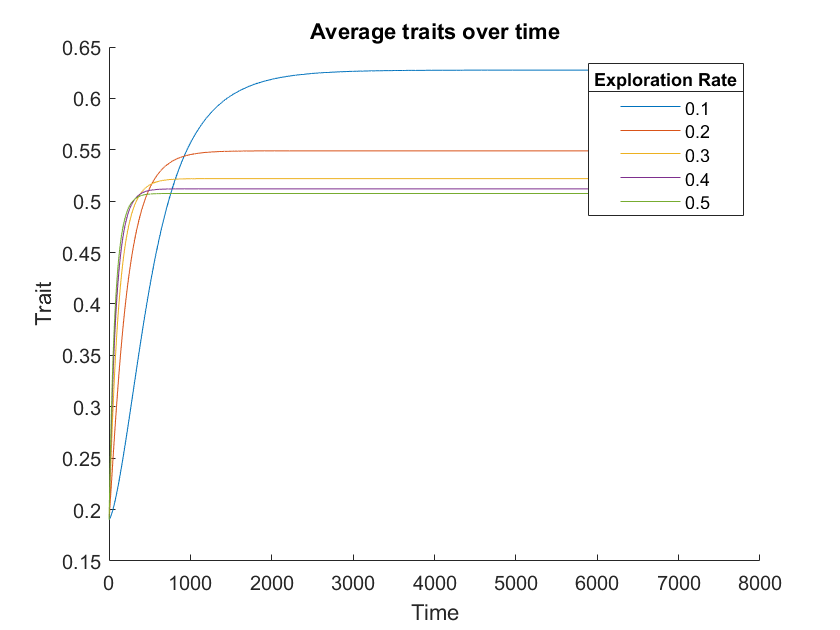

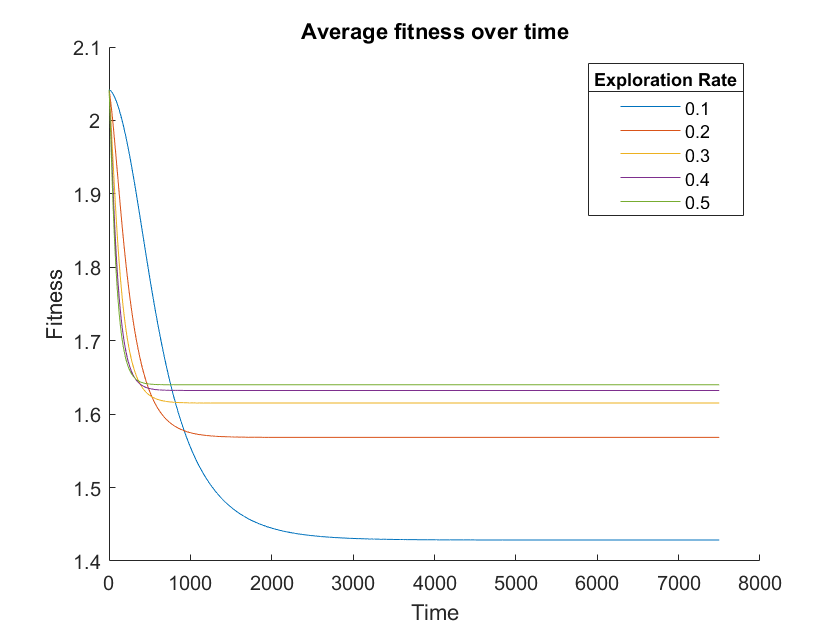

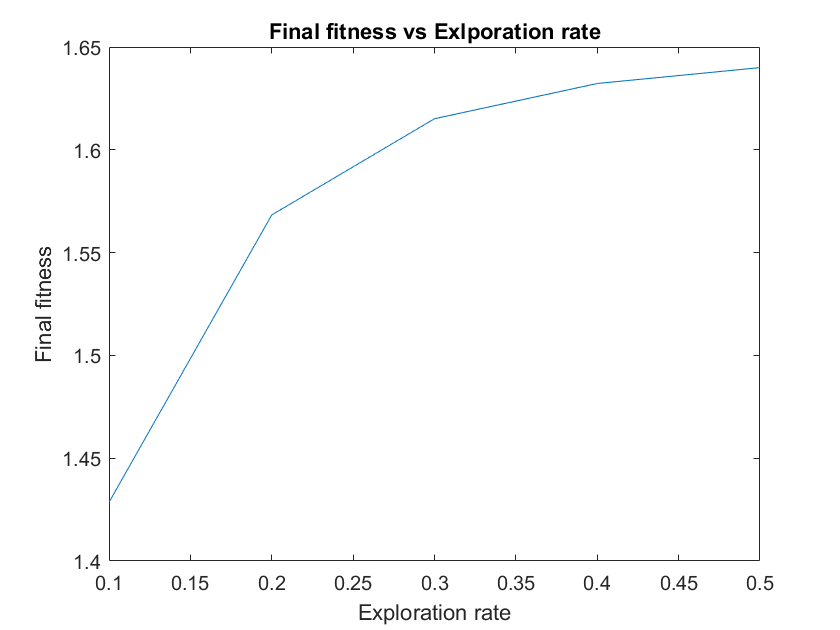

fitness = game_fit(HD(0.75));
spread_matrix_funct = @(u,n_strats) trunc_spread_matrix(u, spread_funct, n_strats);
%spread_matrix_funct = @(u,n_strats) accum_spread_matrix(u, spread_funct, n_strats);

us = [0.1, 0.2, 0.3, 0.4, 0.5]; % mutation rates to run. 
query_us   = 0.05*(1:11); % should span a bit more than the us. 

n_strats  = 101;  % fineness of strategy space discretization
delta_t   = 0.01; % time step for solving the Replicator-Mutator Equation
n_steps   = 7500;
init_dist = zeros(n_strats,1);
init_dist(20) = 1;
init_dist = init_dist / sum(init_dist);

[avg_strats_record, avg_fit_record, dist_record] = all_the_plots(fitness, spread_matrix_funct, us, ...
    query_us, n_strats, delta_t, n_steps, init_dist); % could make separate functions for each plotting. 

## SH initialized below 0.5

In the final game, the initialization creates different results. 

Elapsed time is 16.646386 seconds.
Elapsed time is 9.028484 seconds.
Elapsed time is 9.118480 seconds.
Elapsed time is 10.089521 seconds.
Elapsed time is 9.669165 seconds.


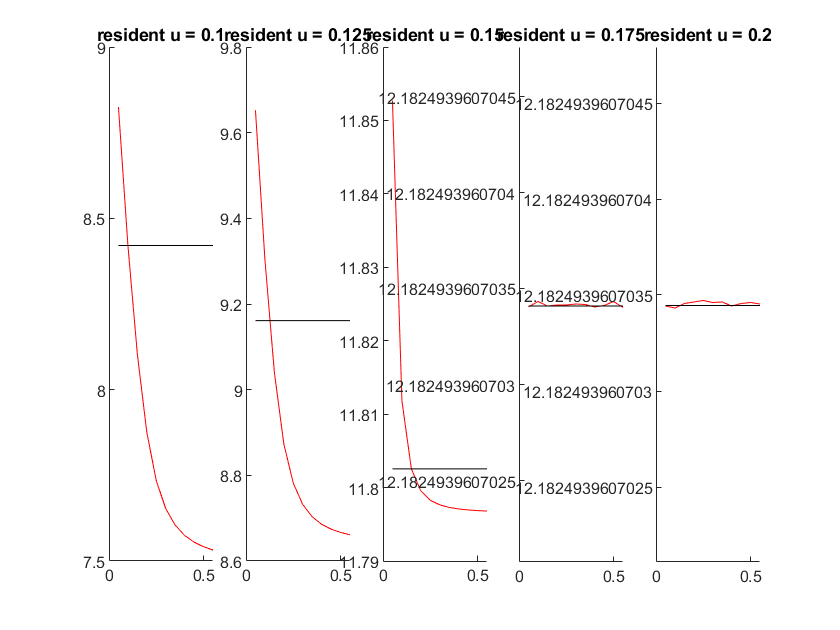

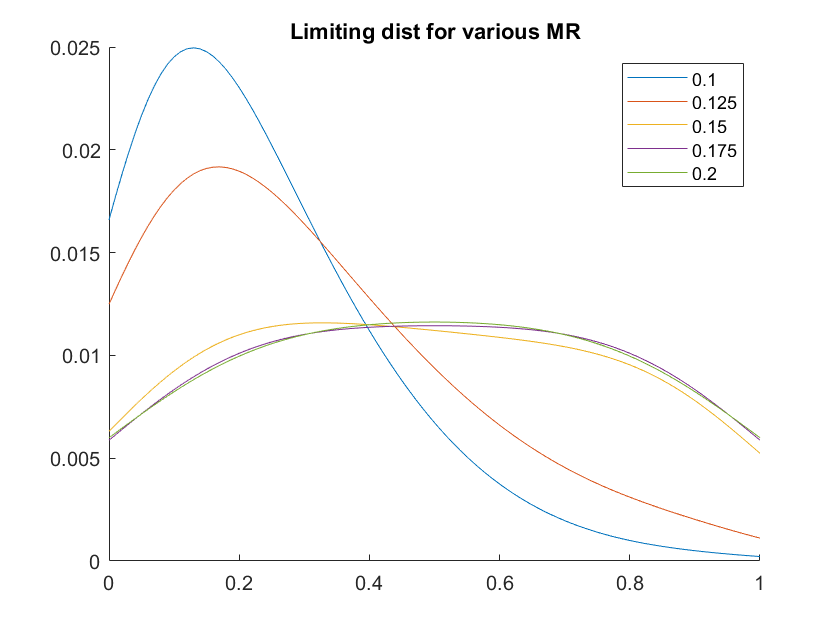

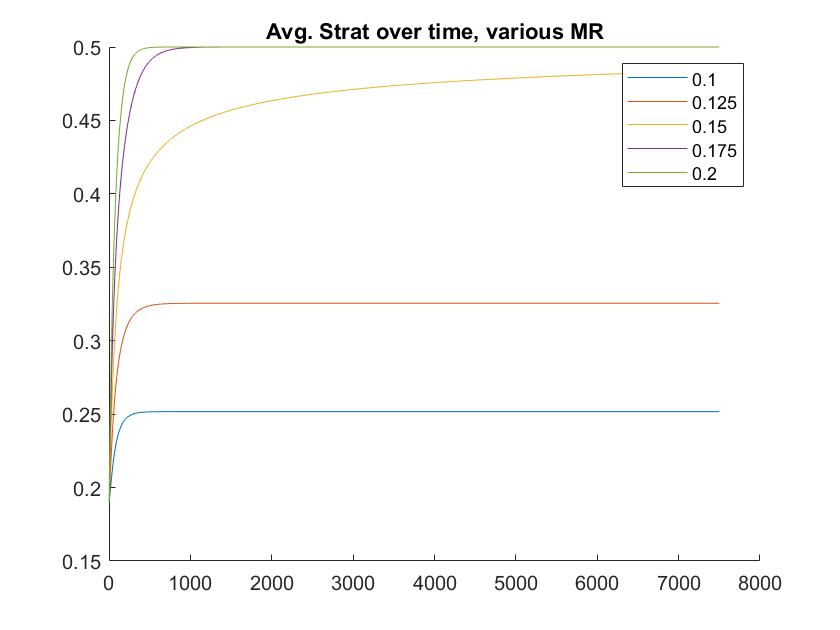

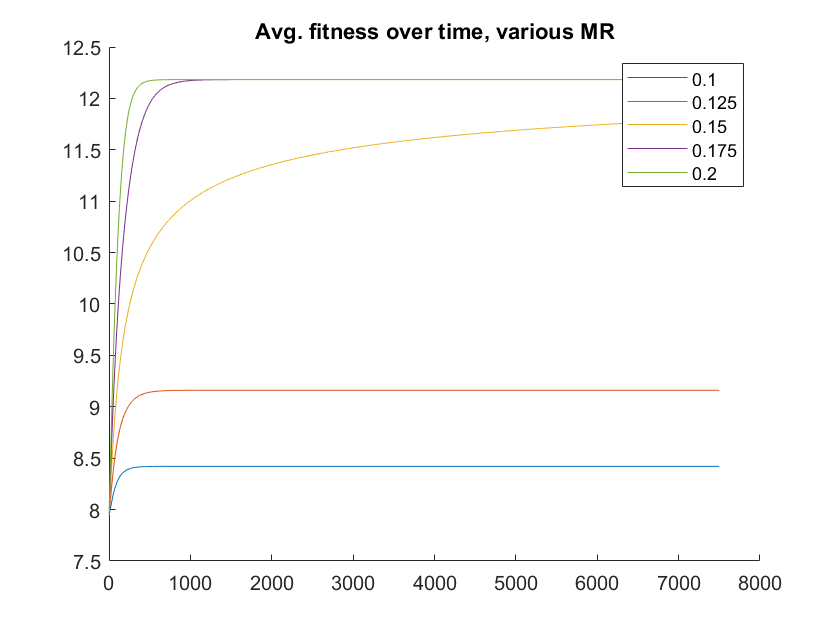

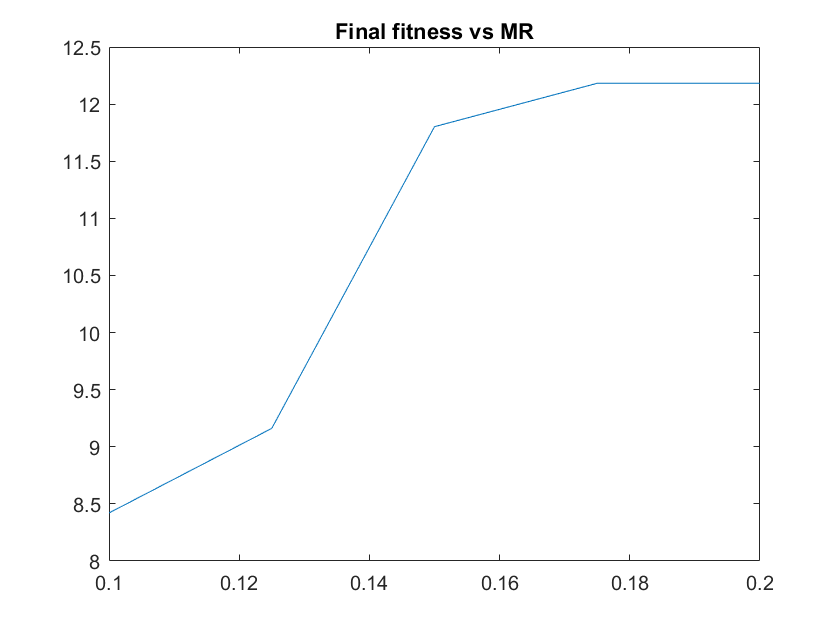

fitness = game_fit(SH);
spread_matrix_funct = @(u,n_strats) trunc_spread_matrix(u, spread_funct, n_strats);
%spread_matrix_funct = @(u,n_strats) accum_spread_matrix(u, spread_funct, n_strats);

us = [0.1, 0.125, 0.15, 0.175, 0.2]; % mutation rates to run. 
query_us   = 0.05*(1:11); % should span a bit more than the us. 

n_strats  = 101;  % fineness of strategy space discretization
delta_t   = 0.01; % time step for solving the Replicator-Mutator Equation
n_steps   = 7500;
init_dist = zeros(n_strats,1);
init_dist(20) = 1;
init_dist = init_dist / sum(init_dist);

[avg_strats_record, avg_fit_record, dist_record] = all_the_plots(fitness, spread_matrix_funct, us, ...
    query_us, n_strats, delta_t, n_steps, init_dist); % could make separate functions for each plotting. 

## SH initialized above 0.5

Elapsed time is 9.623017 seconds.
Elapsed time is 8.974165 seconds.
Elapsed time is 11.010732 seconds.
Elapsed time is 9.078066 seconds.
Elapsed time is 8.924775 seconds.


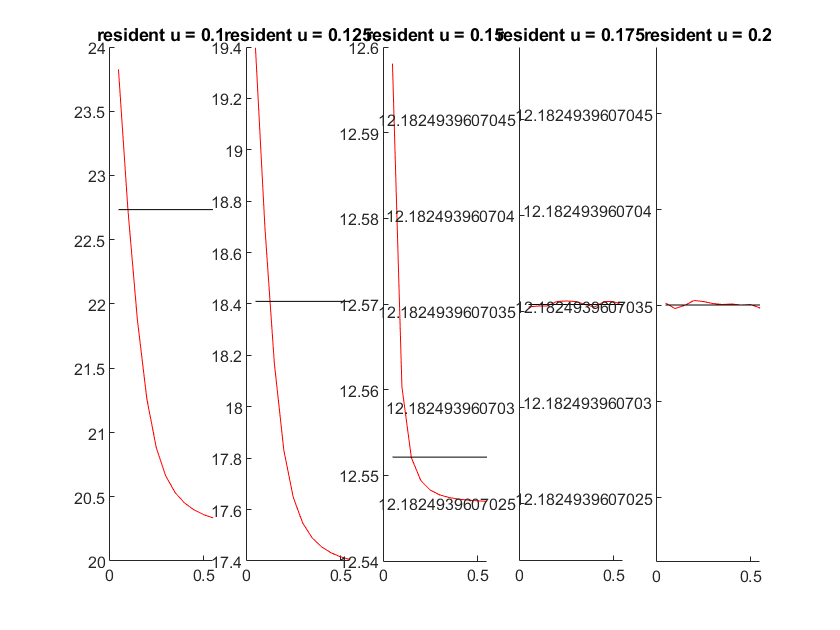

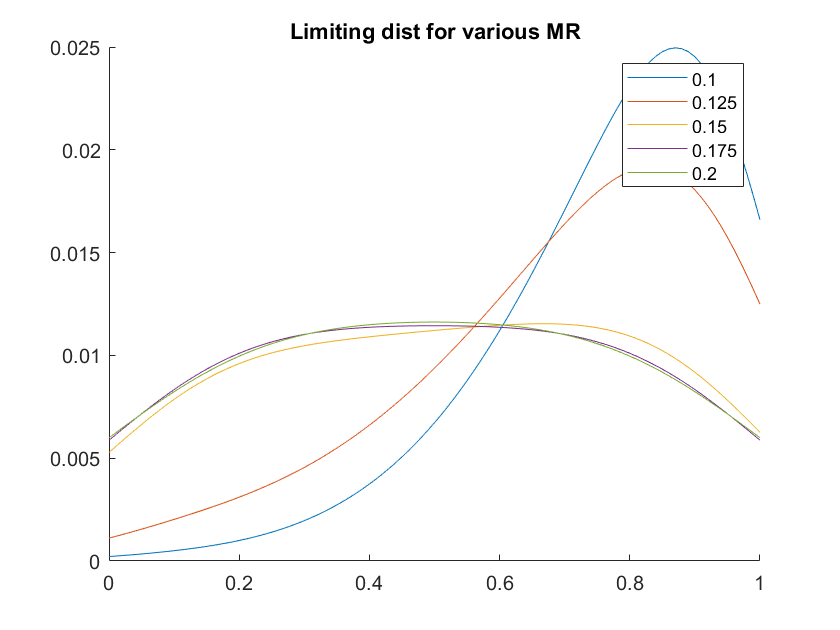

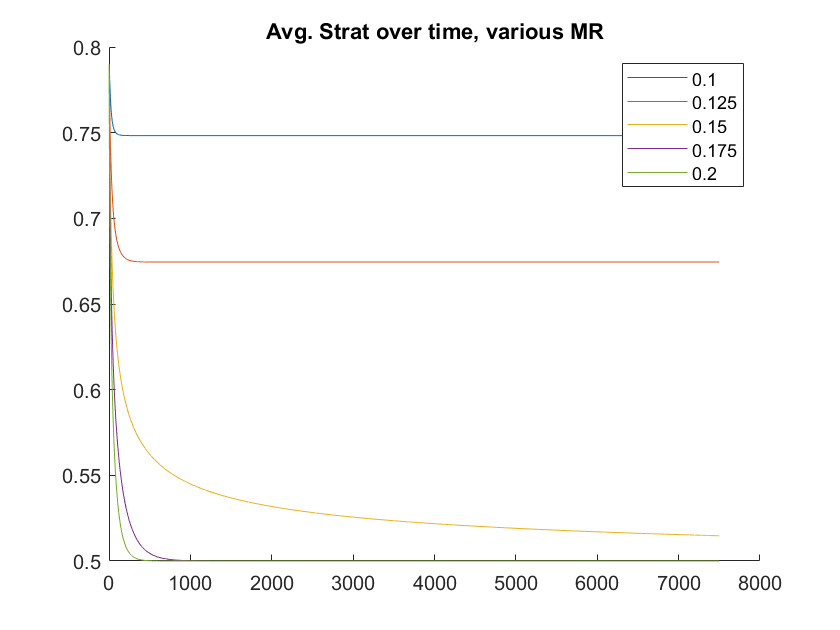

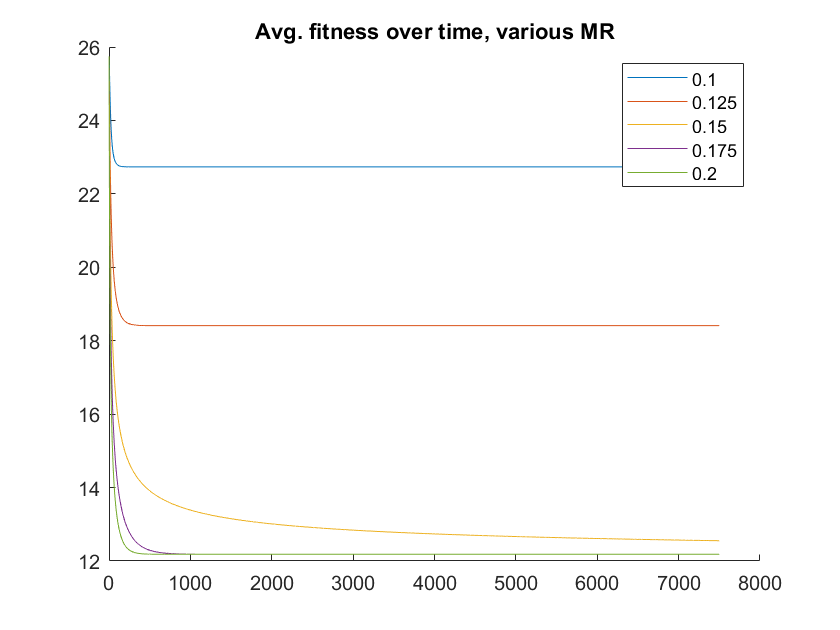

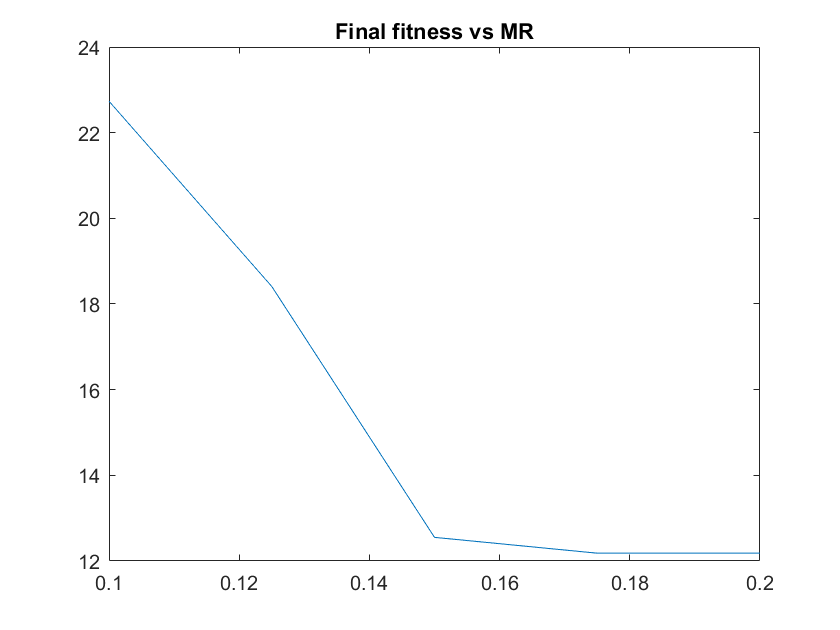

fitness = game_fit(SH);
spread_matrix_funct = @(u,n_strats) trunc_spread_matrix(u, spread_funct, n_strats);
%spread_matrix_funct = @(u,n_strats) accum_spread_matrix(u, spread_funct, n_strats);

us = [0.1, 0.125, 0.15, 0.175, 0.2]; % mutation rates to run. 
query_us   = 0.05*(1:11); % should span a bit more than the us. 

n_strats  = 101;  % fineness of strategy space discretization
delta_t   = 0.01; % time step for solving the Replicator-Mutator Equation
n_steps   = 7500;
init_dist = zeros(n_strats,1);
init_dist(80) = 1;
init_dist = init_dist / sum(init_dist);

[avg_strats_record, avg_fit_record, dist_record] = all_the_plots(fitness, spread_matrix_funct, us, ...
    query_us, n_strats, delta_t, n_steps, init_dist); % could make separate functions for each plotting. 

# Time Varying Fitness

Here we plot the time averaged fitness vs exploration rate, for several periods of environmental change. 

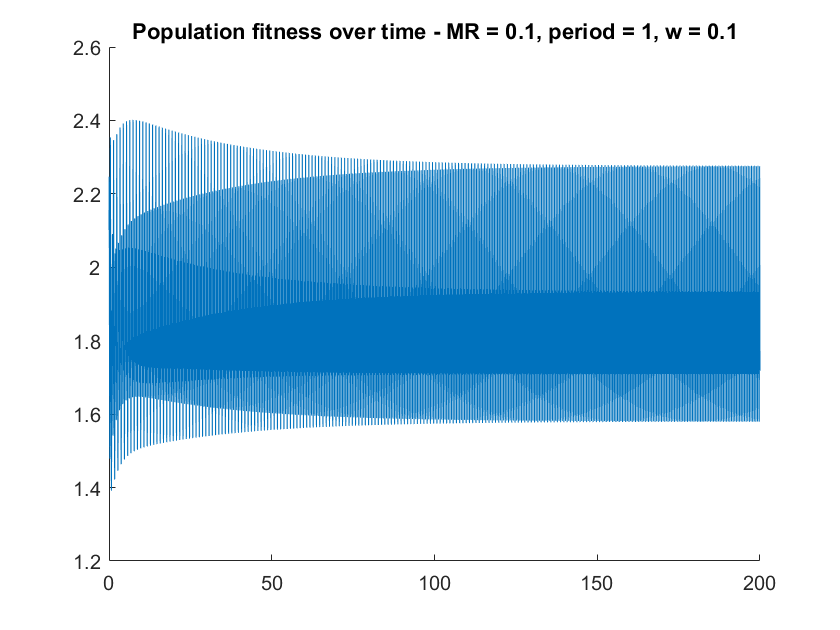

Elapsed time is 115.316958 seconds.


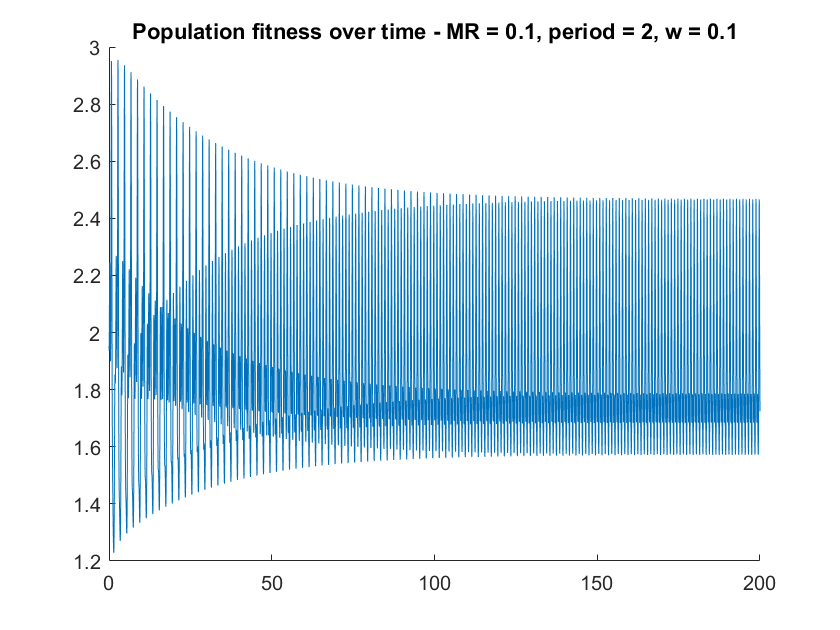

Elapsed time is 152.666854 seconds.


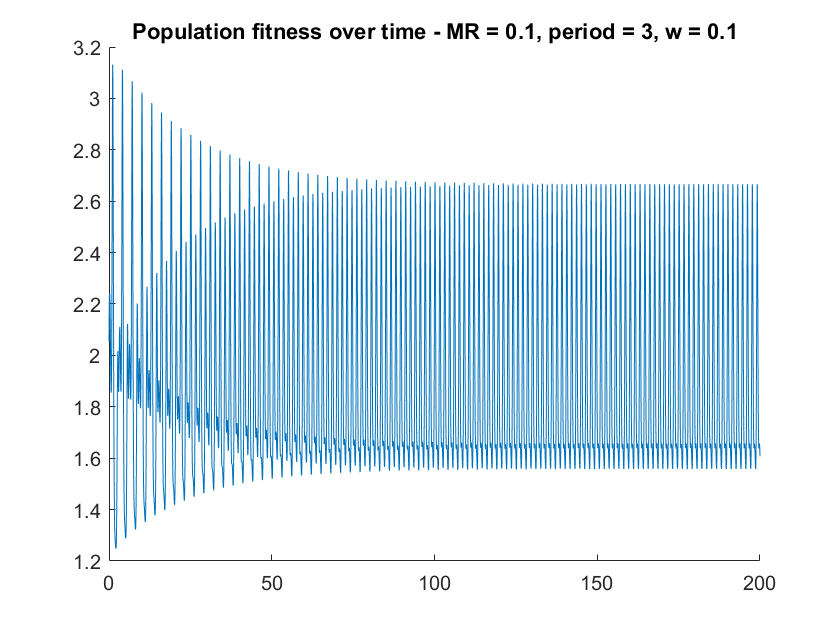

Elapsed time is 117.351214 seconds.


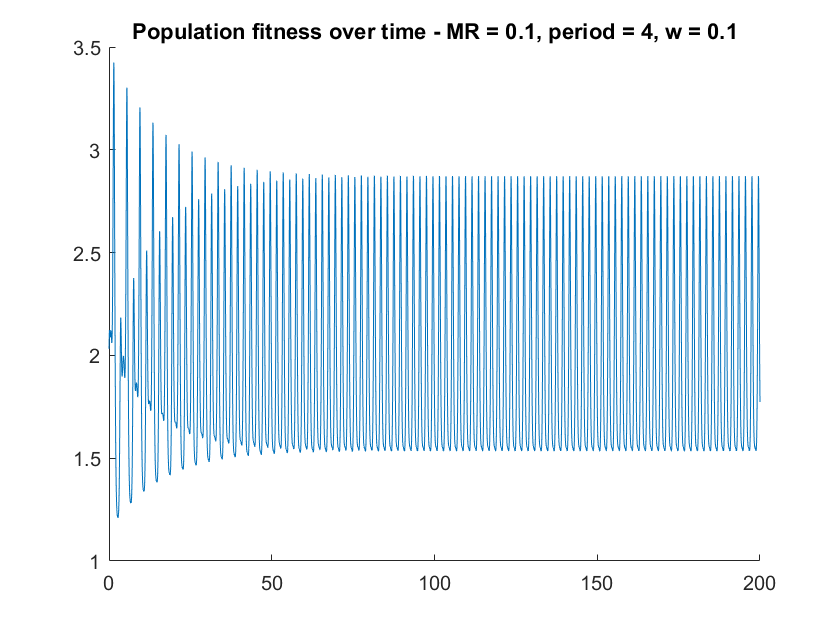

Elapsed time is 111.110959 seconds.


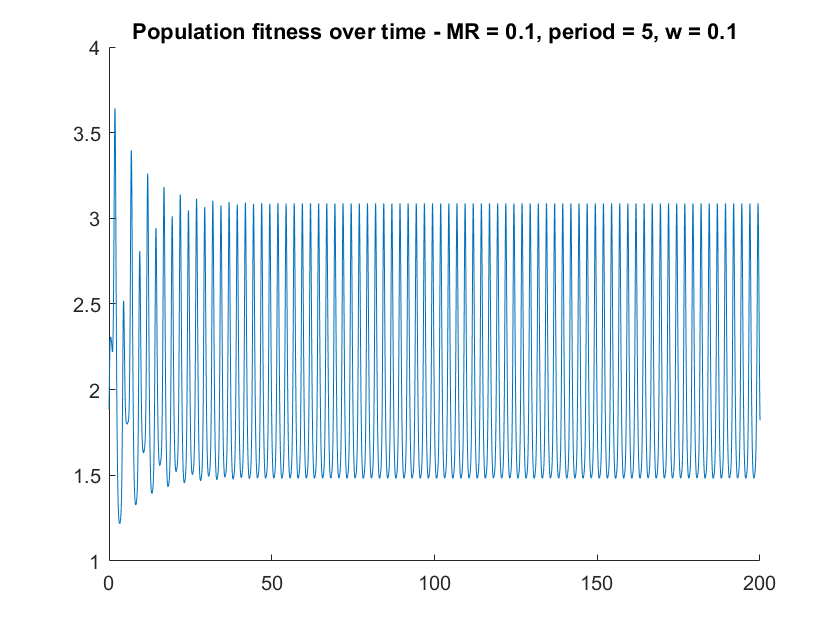

Elapsed time is 115.273090 seconds.


w = 0.1;
periods = 1:5; % can extend to smaller, but they take longer to converge
us = [linspace(0.1,0.5,30), linspace(0.5,1.5,10)];

n_strats = 101;
delta_t = 0.01;
n_steps = ones(5,40)*20000;
to_plot = [1]; % the first of each one, to confirm the dynamics have converged, that is, the plot looks periodic over the last half
spread_matrix_funct = @(u,n_strats) trunc_spread_matrix(u, normal, n_strats);

fitness_record = zeros(length(periods), length(us));
for i=1:length(periods)
    tic
    fitness_record(i,:) = time_sim(w, periods(i), us, n_strats, delta_t, n_steps(i,:), to_plot, spread_matrix_funct);
    fprintf("\n")
    toc
end

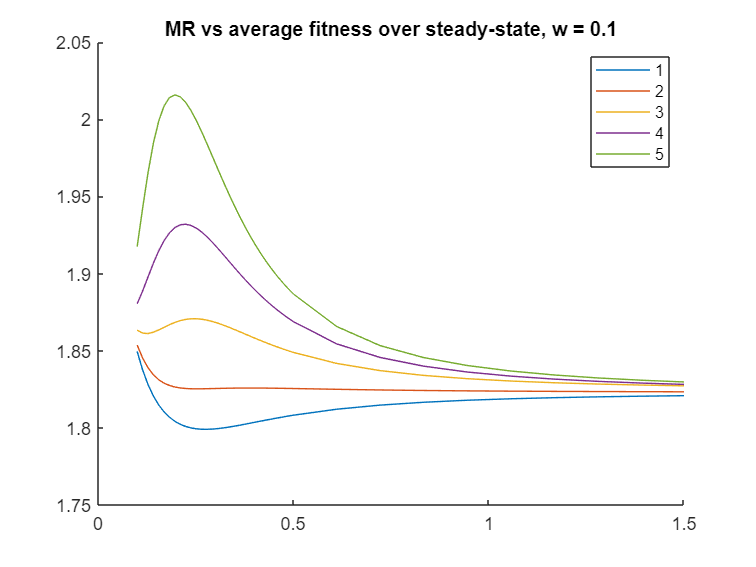


figure
hold on
for i=1:length(periods)
    plot(us, fitness_record(i,:))
end
hold off
xlabel("Exploration rate")
ylabel("Average fitness over steady state")
title("Exploration rate vs Average fitness")
lgd = legend(strsplit(num2str(periods), ' '));
title(lgd,'Period')

## Larger w

Here we check what happens when a wider fitness is used, for a less hash landscape, then we check a smaller width. 

w = 0.2;
periods = 1:5; % can extend to smaller, but they take longer to converge
us = linspace(0.1,2,20);

n_strats = 101;
delta_t = 0.01;
n_steps = ones(5,20)*20000;
to_plot = [1];
spread_matrix_funct = @(u,n_strats) trunc_spread_matrix(u, normal, n_strats);

fitness_record = zeros(length(periods), length(us));
for i=1:length(periods)
    tic
    fitness_record(i,:) = time_sim(w, periods(i), us, n_strats, delta_t, n_steps(i,:), to_plot, spread_matrix_funct);
    fprintf("\n")
    toc
end

figure
hold on
for i=1:length(periods)
    plot(us, fitness_record(i,:))
end
hold off
title("MR vs average fitness over steady-state, w = " + w)
legend(strsplit(num2str(periods), ' '))

## Smaller w

w = 0.05;
periods = 1:5; % can extend to smaller, but they take longer to converge
us = linspace(0.1,2,20);

n_strats = 101;
delta_t = 0.01;
n_steps = [10, 4, 2, ones(1,17); % determined by inspection, when average fitness
            6, 2, ones(1,18); % becomes periodic. 
            2, 2, ones(1,18);
            ones(1,20);
            ones(1,20)]*20000;
to_plot = [1, 2];
spread_matrix_funct = @(u,n_strats) trunc_spread_matrix(u, normal, n_strats);

fitness_record = zeros(length(periods), length(us));
for i=1:length(periods)
    tic
    fitness_record(i,:) = time_sim(w, periods(i), us, n_strats, delta_t, n_steps(i,:), to_plot, spread_matrix_funct);
    fprintf("\n")
    toc
end

figure
hold on
for i=1:length(periods)
    plot(us, fitness_record(i,:))
end
hold off
title("MR vs average fitness over steady-state, w = " + w)
legend(strsplit(num2str(periods), ' '))

# Circular trait space

Lastly, we change the mutation to make the trait space circular, so exploration wraps around 0 and 1. This doesn't seem to show the same effect, suggesting the previous is a consequence of the peak staying around the endpoints. 

w = 0.1;
periods = 2.^(0:3); % can extend to smaller, but they take longer to converge
us = linspace(0.1,2,20);

n_strats = 101;
delta_t = 0.01;
n_steps = 10000*ones(1, length(us));
to_plot = [];
spread_matrix_funct = @(u,n_strats) circ_spread_matrix(u, normal, n_strats);

fitness_record = zeros(length(periods), length(us));
for i=1:length(periods)
    c = clock;
    fitness_record(i,:) = time_sim(w, periods(i), us, n_strats, delta_t, n_steps, to_plot, spread_matrix_funct);
    fprintf("\n")
    d = clock-c; % because nested tic toc didn't seem to work
    fprintf("Took " + (60*d(5)+d(6)) + " seconds. "); % ignores hours
end

Took 28.726 seconds. Took 28.824 seconds. Took 29.291 seconds. Took 36.933 seconds. 

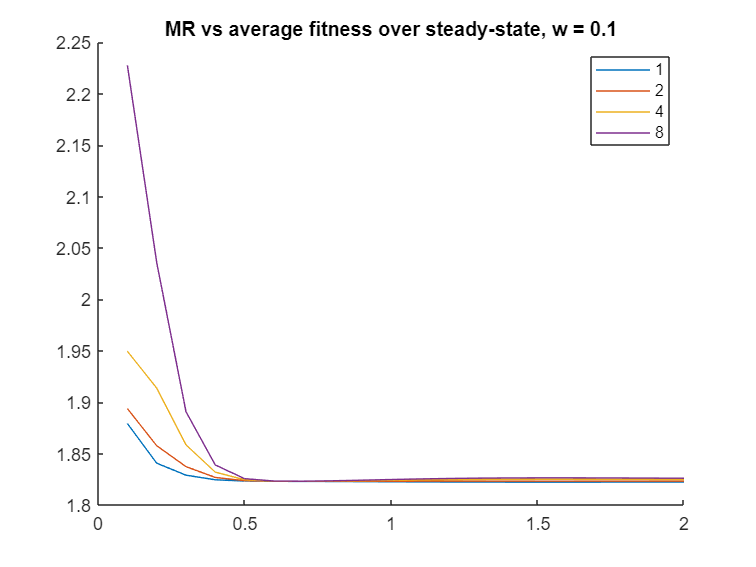


figure
hold on
for i=1:length(periods)
    plot(us, fitness_record(i,:))
end
hold off
title("MR vs average fitness over steady-state, w = " + w)
legend(strsplit(num2str(periods), ' '))

## Functions

function result = normpdf(xs, mu, sigma)
    result = exp(-0.5*((xs-mu)/sigma).^2)/(sigma*sqrt(2*pi));
end

function result = geomean(L) 
    %result = prod(L)^(1/length(L)); % will become 0 or infinite if L large
    result = exp(mean(log(L)));
end

function new_dist = advance(dist, spread, growth, delta_t) 
    dxdt = (spread*growth-sum(growth*dist)*eye(size(growth)))*dist;
    new_dist = dist+delta_t*dxdt;
end

function vals = init(n) % samples uniformly from the simplex, 
    xs = rand(1,n-1);
    xs = sort([0, xs, 1]);
    vals = arrayfun(@(i) xs(i+1)-xs(i), 1:(length(xs)-1))';
end

% Code for the spread matrices
function spread = trunc_spread_matrix(u, spread_funct, n)
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n
        spread(r,:) = spread_funct(strats, strats(r), u);
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = accum_spread_matrix(u, spread_funct, n)
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n % evaluate the spread function at 1/n spacing, and group values beyond boundary
        vals = spread_funct(linspace(-5,6,11*n), strats(r), u);
        spread(r,:) = vals(1,(5*n+1):6*n); 
        spread(r,1) = spread(r,1) + sum(vals(1, 1:5*n));
        spread(r,n) = spread(r,n) + sum(vals(1, (6*n+1):11*n));

        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = circ_spread_matrix(u, spread_funct, n)
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n
        vals = spread_funct(linspace(-2,3,5*n), strats(r), u);
        spread(r,:) = vals(1:n) + vals((n+1):2*n) + vals((2*n+1):3*n) + ...
            vals((3*n+1):4*n) + vals((4*n+1):5*n);
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = unif_spread_matrix(u,~,n)
    spread = (1-u)*eye(n) + (u/n)*ones(n, n);
end

function spread = integ_accum_spread_matrix(u, spread_funct, n) % takes much longer
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n % integrate between midpoints of discretization
        spread(r,1) = integral(@(x) spread_funct(x, strats(r), u), ...
                -5, (strats(1)+strats(2))/2);
        for c=2:(n-1)
            spread(r,c) = integral(@(x) spread_funct(x, strats(r), u), ...
                (strats(c)+strats(c-1))/2, (strats(c)+strats(c+1))/2);
        end
        spread(r,n) = integral(@(x) spread_funct(x, strats(r), u), ...
                (strats(n-1)+strats(n))/2, 6);
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = integ_trunc_spread_matrix(u, spread_funct, n) % takes much longer
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n % integrate between midpoints of discretization
        spread(r,1) = integral(@(x) spread_funct(x, strats(r), u), ...
                -1/(2*(n-1)), (strats(1)+strats(2))/2);
        for c=2:(n-1) % bin for enpoints goes beyond 0,1 so they are as wide as the others
            spread(r,c) = integral(@(x) spread_funct(x, strats(r), u), ...
                (strats(c)+strats(c-1))/2, (strats(c)+strats(c+1))/2);
        end
        spread(r,n) = integral(@(x) spread_funct(x, strats(r), u), ...
                (strats(n-1)+strats(n))/2, 1+1/(2*(n-1)));
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end






function [avg_strats, avg_fit, dist] = run_model(fitness, u, spread_matrix_funct, n_strats, delta_t, n_steps, init_dist)
    avg_strats  = zeros(1,n_steps);
    avg_fit     = zeros(1,n_steps);
    dist   = init_dist;
    strats = linspace(0,1,n_strats);
    tic
    for i=1:n_steps
        % Update growth matrix and trait distribution
        growth = zeros(n_strats,n_strats);
        growth(sub2ind(size(growth), 1:n_strats, 1:n_strats)) = fitness(delta_t*i, dist, strats);
        
        avg_strats(i) = strats*dist;
        avg_fit(i) = sum(growth*dist);
        
        dist = advance(dist, spread_matrix_funct(u,n_strats), growth, delta_t);
    end
    toc
end

function [avg_strats_record, avg_fit_record, dist_record] = all_the_plots(fitness, spread_matrix_funct, ...
            us, query_us, n_strats, delta_t, n_steps, init_dist)
    % Run the simulation
    avg_strats_record = zeros(length(us), n_steps);
    avg_fit_record = zeros(length(us), n_steps);
    dist_record = zeros(length(us), n_strats);
    for i=1:length(us)
        [avg_strats, avg_fit, dist] = run_model(fitness, us(i), spread_matrix_funct, n_strats, delta_t, n_steps, init_dist);
        avg_strats_record(i,:) = avg_strats;
        avg_fit_record(i,:) = avg_fit;
        dist_record(i,:) = dist;
    end

    % Plot the results
    strats = linspace(0,1,n_strats);
    figure
    %title("Maximum eigenvalue of Q(u)F(x) vs Avg. Fitness")
    for i=1:length(us) % or could do for a subset. 
        resident_u = us(i); 
    
        growth = zeros(n_strats,n_strats);
        growth(sub2ind(size(growth), 1:n_strats, 1:n_strats)) = fitness(delta_t*n_steps, dist_record(i,:)',strats); 
    
        max_eigs = zeros(size(query_us));
        for j=1:length(query_us)
            [V,D] = eig(spread_matrix_funct(query_us(j),n_strats)*growth);
            [max_eig, loc] = max(diag(D));
            max_eigs(j) = max_eig;
        end
        
        subplot(1,length(us),i)
        hold on
        plot(query_us, max_eigs-avg_fit_record(i,end)*ones(size(query_us)));
        plot(query_us, zeros(size(query_us)),'k-');
        %plot(query_us, max_eigs, 'r');
        %plot(query_us, avg_fit_record(i,end)*ones(size(query_us)), 'k-');
        xlabel("Exploration rate")
        ylabel("Invasion fitness")
        title("Invasion Fitness, resident u = " + resident_u)
        hold off
    end
    
    
    figure
    hold on
    for i=1:length(us)
        plot(strats,dist_record(i,:));
    end
    xlabel("Trait")
    ylabel("Frequency")
    title("Limiting distibutions")
    lgd = legend(strsplit(num2str(us), ' '));
    title(lgd,'Exploration Rate')
    hold off
    
    figure
    hold on
    for i=1:length(us)
        plot(1:n_steps,avg_strats_record(i,:));
    end
    xlabel("Time")
    ylabel("Trait")
    title("Average traits over time")
    lgd = legend(strsplit(num2str(us), ' '));
    title(lgd,'Exploration Rate')
    hold off
    
    figure
    hold on
    for i=1:length(us)
        plot(1:n_steps,avg_fit_record(i,:));
    end
    xlabel("Time")
    ylabel("Fitness")
    title("Average fitness over time") % read last entry for ordering. 
    lgd = legend(strsplit(num2str(us), ' '));
    title(lgd,'Exploration Rate')
    hold off
    
    figure
    plot(us, avg_fit_record(:, end))
    xlabel("Exploration rate")
    ylabel("Final fitness")
    title("Final fitness vs Exlporation rate")
end

function avg_fit = time_sim(w, period, us, n_strats, delta_t, n_steps, to_plot, spread_matrix_funct)
    fitness = @(t,dist,strats) 1+normpdf(strats, (1+sin(2*pi*t/period))/2, w);

    strats    = linspace(0,1,n_strats);
    avg_fit   = zeros(size(us));
    init_dist = init(n_strats);
    for j=1:length(us)  
        spread  = spread_matrix_funct(us(j),n_strats);
        pop_fit = zeros(1,n_steps(j));
        dist    = init_dist;

        %tic
        for i=1:n_steps(j)
            % Update growth matrix and trait distribution
            growth = zeros(n_strats,n_strats);
            growth(sub2ind(size(growth), 1:n_strats, 1:n_strats)) = fitness(delta_t*i, dist, strats);
            
            pop_fit(i) = sum(growth*dist);
            
            dist = advance(dist, spread, growth, delta_t);
        end
        
        if ismember(j,to_plot) % to verify the fitness is in steady state. 
            figure
            hold on
            plot(delta_t*(1:n_steps(j)), pop_fit)
            title("Population fitness over time - MR = " + us(j) + ...
                ", period = " + period + ", w = " + w)
            hold off
            drawnow
        end
        
        avg_fit(j) = geomean(pop_fit(floor(0.5*end):end)); % geometric mean
        %toc % as population grown geometrically. Sample last half to average
    end % over steady state. 
end